Primeiro, vamos definir a função no domínio contínuo de Laplace.

sys = tf([1, 2], [1, 0.6, -10])

sys =        s + 2
  ----------------
  s^2 + 0.6 s - 10
 
Continuous-time transfer function.


Agora, vamos calcular os seus polos e verificar a sua estabilidade através de uma entrada degrau.

pole(sys)

ans =    -3.4765
    2.8765


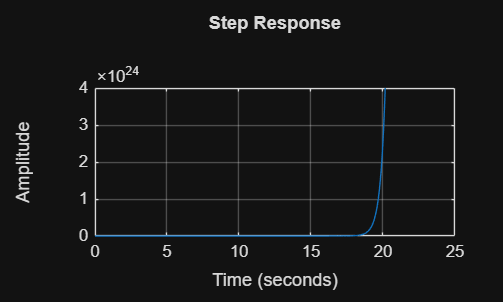

figure
step(sys)
grid on

Vejamos também a resposta ao impulso do sistema em malha aberta:

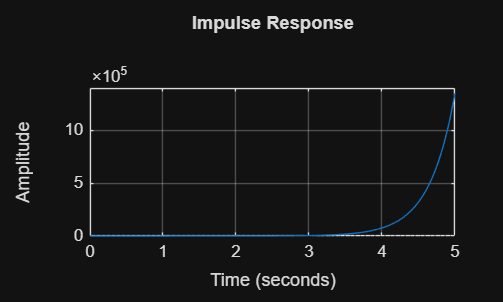

figure
impulse(sys, 5)
grid on

Notamos que o sistema possui um polo em 2.87, o que o torna instável automaticamente, conforme verificado pelo gráfico. Tentando a realimentação pura, vejamos o que acontece a seguir, com a mesma entrada degrau:

sys_realimentado = feedback(sys, 1)

sys_realimentado =        s + 2
  ---------------
  s^2 + 1.6 s - 8
 
Continuous-time transfer function.


pole(sys_realimentado)

ans =    -3.7394
    2.1394


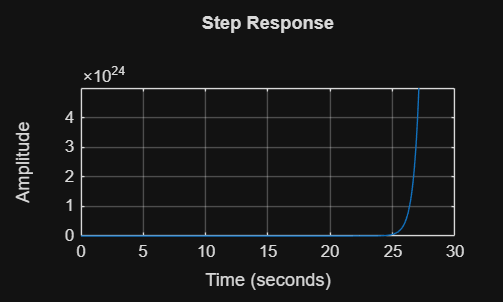

figure
step(sys_realimentado)
grid on

E a resposta ao impulso do sistema realimentado:

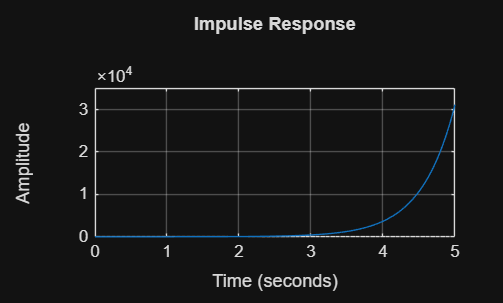

figure
impulse(sys_realimentado, 5)
grid on

Observamos que o sistema continua instável, com um polo presente em 2,13 e uma saída para a entrada degrau que caminha para o infinito. Isso significa que a realimentação por si só não é capaz de estabilizar o sistema, o que significa que há a necessidade de projetar um controlador DIGITAL para este sistema. De início, tentaremos estabilizar o sistema apenas através de um ganho proporcional. Para tal, vamos levar o sistema para o domínio z.

Antes de projetar o controlador, vamos calcular os parâmetros ωn e ξ necessários para o sistema operar conforme a performance solicitada. O ξ vem do overshoot máximo e o ωn vem do tempo de estabelecimento (critério de 2%, te = 4/(ξωn)):

OS    = 0.10;                                 % overshoot máximo
zeta  = -log(OS) / sqrt(pi^2 + log(OS)^2)     % ≈ 0.591

zeta = 0.5912

sigma = 4 / 3;                                % te <= 3 s
wn    = sigma / zeta                          % ≈ 2.26 rad/s

wn = 2.2555

Portanto, o sistema precisa de ξ ≥ 0,591 e ωn ≥ 2,26 rad/s. O tempo de subida (tr ≈ 1,8/ωn ≤ 2 s exige ωn ≥ 0,9 rad/s) já é atendido por esse valor.

Para descobrir a o tempo de amostragem inicial, utilizaremos a heurística definida por Franklin, Powell & Emami-Naeini, *Feedback Control of Dynamic Systems*, cap. 8, que diz que a frequência de amostragem deve ser 20 vezes maior do que a frequência de banda calculada em wB:

wB    = wn * sqrt(1 - 2*zeta^2 + sqrt(4*zeta^4 - 4*zeta^2 + 2));   % banda desejada
T     = 2*pi / (20*wB)                                         

T = 0.1201

Tomado este período de amostragem como ponto de partida, analisaremos o sistema em domínio discreto, convertendo o sistema original.

sys_discreto = c2d(sys, T)

sys_discreto =     0.1329 z - 0.1048
  ----------------------
  z^2 - 2.071 z + 0.9305
 
Sample time: 0.12008 seconds
Discrete-time transfer function.


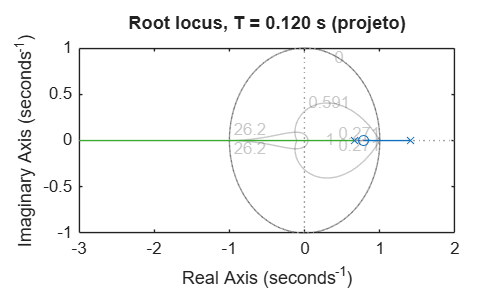

figure
rlocus(sys_discreto)
zgrid(zeta, wn*T) % mostra região de interesse para parâmetros obtidos acima
title(sprintf('Root locus, T = %.3f s (projeto)', T))
% pasta 'figuras' ao lado deste .mlx (e não na pasta atual do MATLAB)
pasta_figuras = fullfile(fileparts(matlab.desktop.editor.getActiveFilename), 'figuras');
if ~exist(pasta_figuras, 'dir'), mkdir(pasta_figuras), end
theme(gcf, 'light')
exportgraphics(gcf, fullfile(pasta_figuras, sprintf('rlocus_projeto_T_%.3f.png', T)), 'Resolution', 300)

Agora, utilizaremos a rltool() para mover os polos para uma posição de estabilidade (até step estabilizar) e extrair o ganho de forma que os nossos requisitos sejam atendidos.

%rltool(sys_discreto)

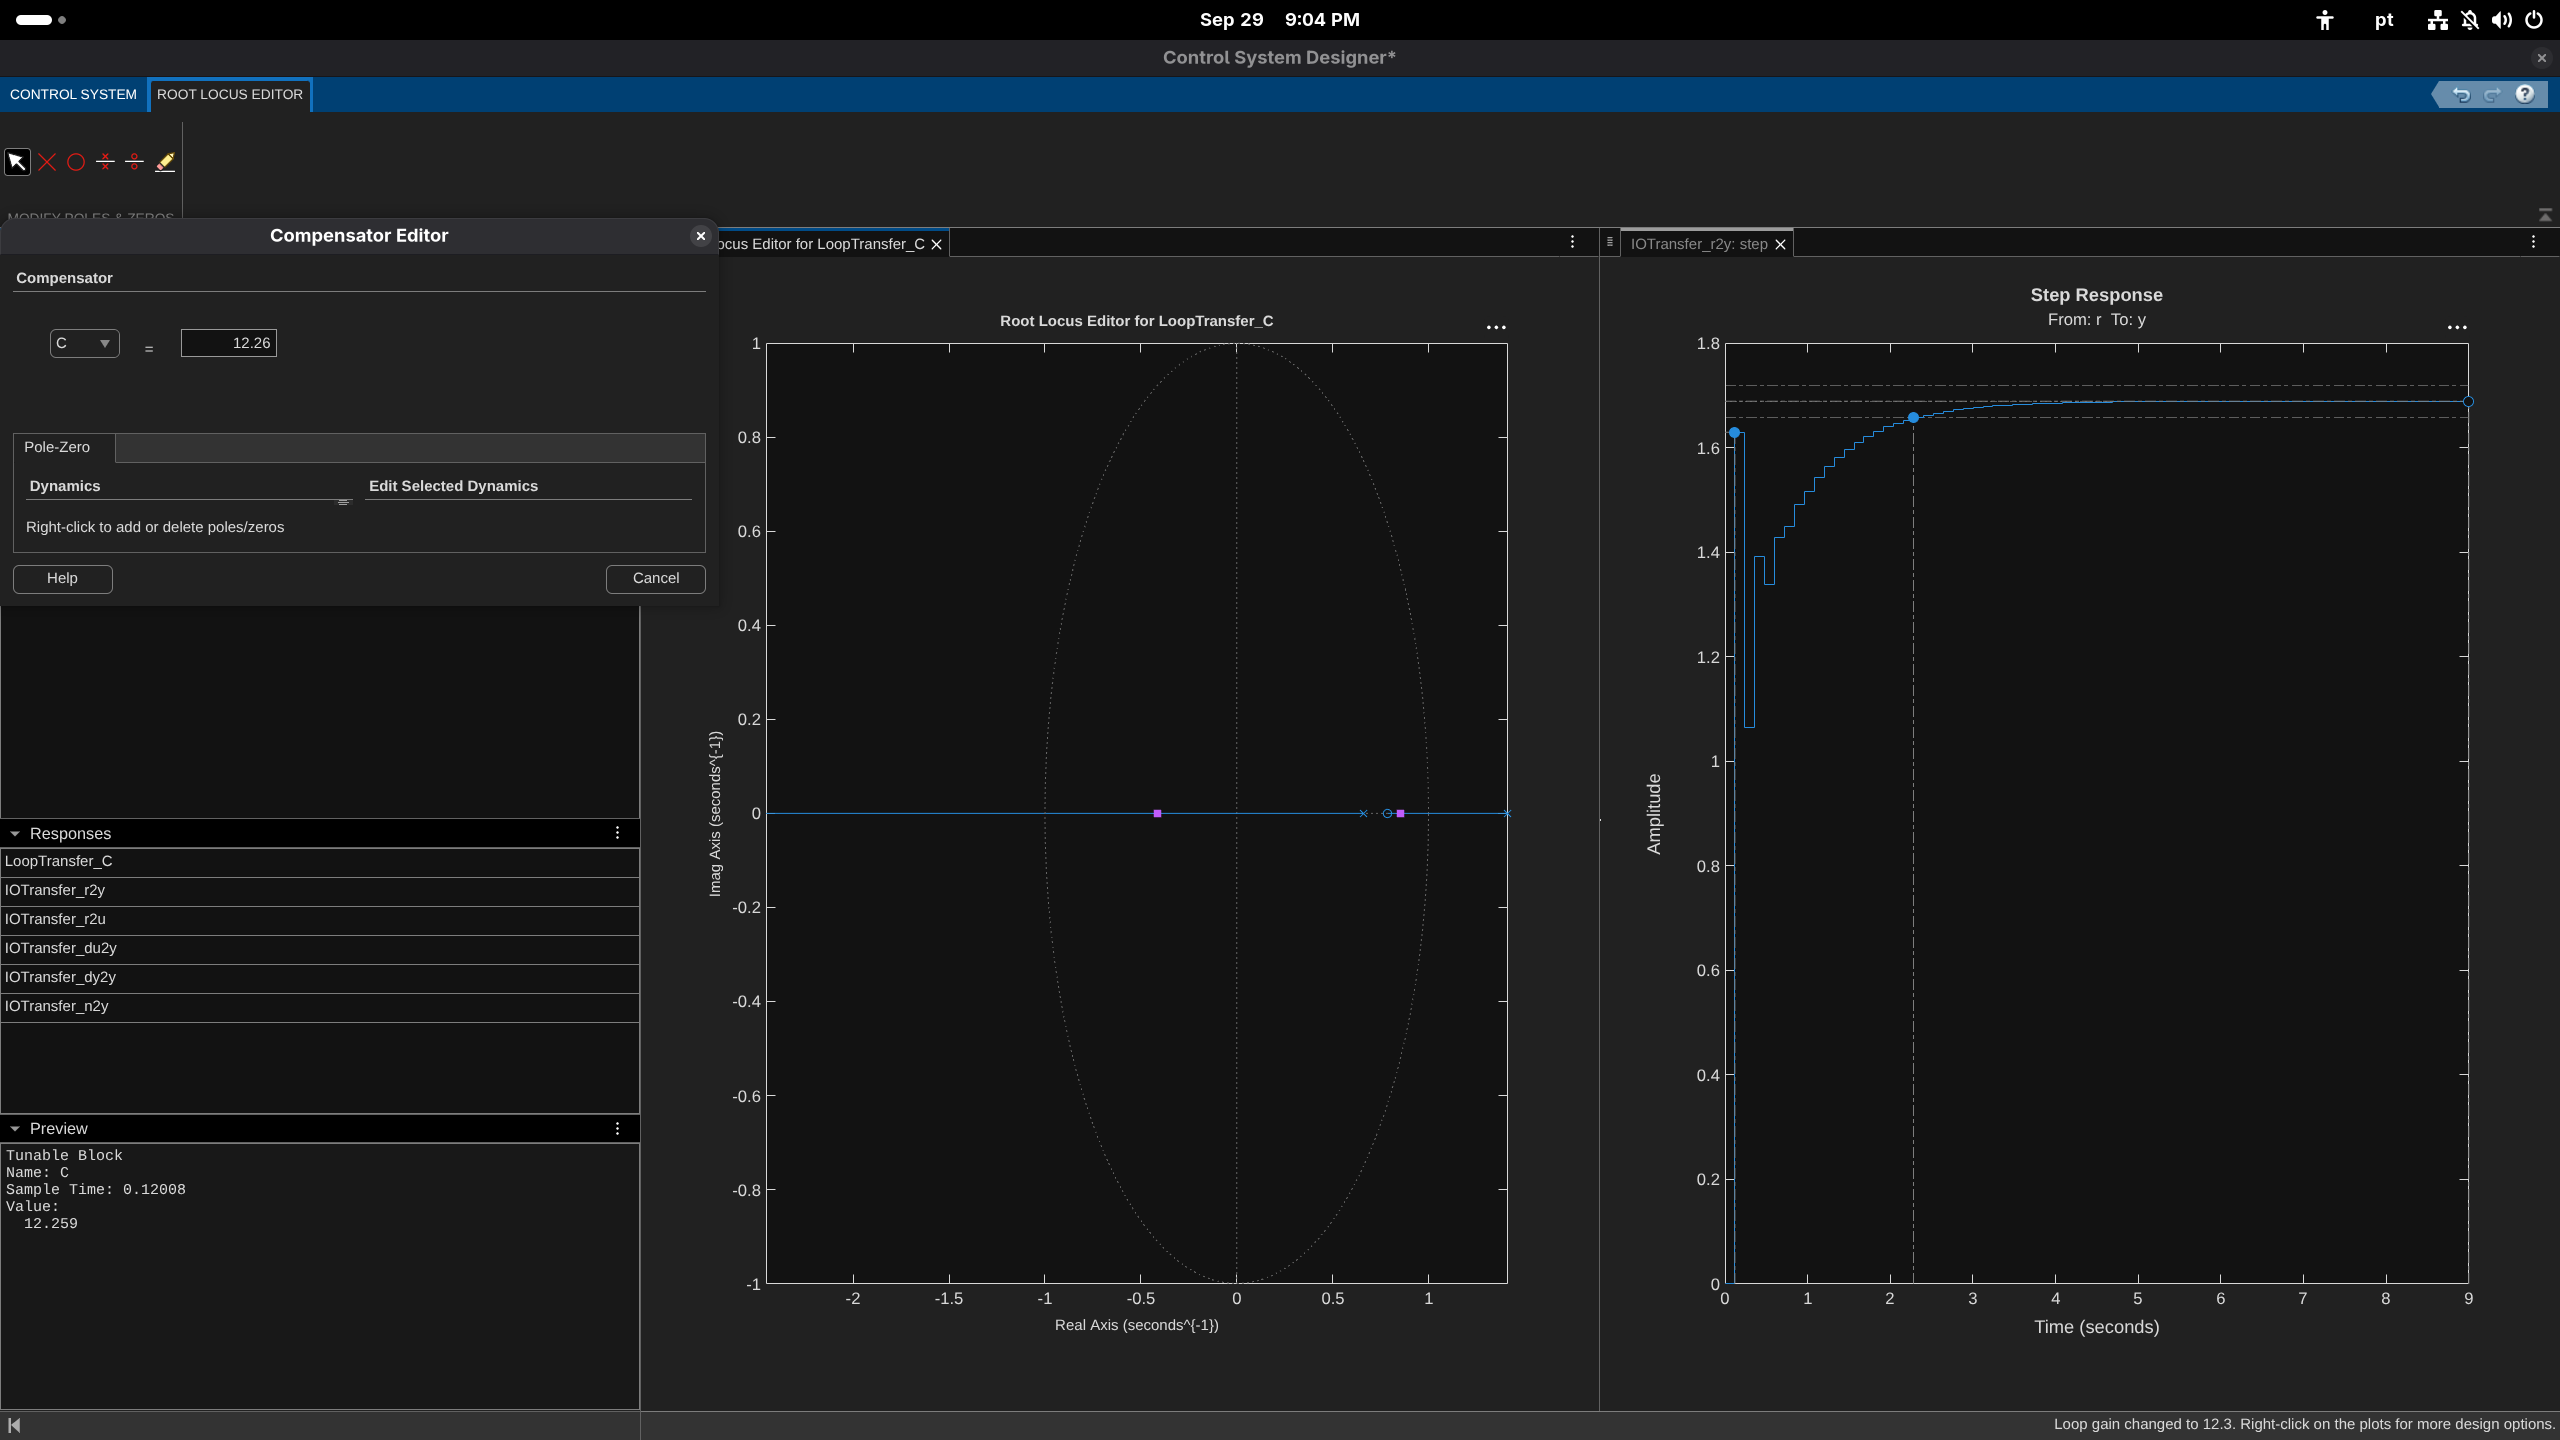

Ajustando os polos, obtemos um Tempo de Subida de 0 segundos (inferior a 2), um Tempo de Estabelecimento de 2,28s e um overshoot de 0%. Analisando o ganho na variável C, obtemos 12,26. Com este ganho K obtido, vamos para o simulink.

K = 12.26;
[numd, dend] = tfdata(sys_discreto, 'v')   % coeficientes para o bloco Discrete Transfer Fcn

numd =          0    0.1329   -0.1048


dend =     1.0000   -2.0713    0.9305


No Simulink, comparamos a saída do sistema discreto visto pelo controlador (bloco Discrete Transfer Fcn) com a do sistema real contínuo controlado digitalmente (ZOH + planta contínua). As duas saídas coincidem nos instantes de amostragem kT, o que confirma que G(z) representa corretamente a planta vista pelo controlador. Entre as amostras, a planta contínua apresenta uma leve oscilação alternada, causada pelo polo de malha fechada no eixo real negativo (z ≈ −0,41).

Agora, faremos a varredura para descobrir a frequência mínima de amostragem para que o sistema discreto realimentado seja estável. Para cada T, verificamos se existe algum K que estabiliza a malha fechada:

K_testados = linspace(5, 30, 5000);   % K < 5 nunca estabiliza

for T_teste = [0.30 0.40 0.44 0.45 0.46 0.47 0.50]
    sys_discreto_teste = c2d(sys, T_teste, 'zoh');
    existe_K_estavel = any(arrayfun(@(k) isstable(feedback(k*sys_discreto_teste, 1)), K_testados));
    fprintf('T = %.2f s | fs = %.2f Hz | existe K estável: %d\n', T_teste, 1/T_teste, existe_K_estavel);
end

T = 0.30 s | fs = 3.33 Hz | existe K estável: 1
T = 0.40 s | fs = 2.50 Hz | existe K estável: 1
T = 0.44 s | fs = 2.27 Hz | existe K estável: 1
T = 0.45 s | fs = 2.22 Hz | existe K estável: 1
T = 0.46 s | fs = 2.17 Hz | existe K estável: 1
T = 0.47 s | fs = 2.13 Hz | existe K estável: 0
T = 0.50 s | fs = 2.00 Hz | existe K estável: 0


Traçamos o root locus no limite, marcando os ganhos em que o locus cruza o círculo unitário em z = 1 (entrada) e em z = −1 (saída):

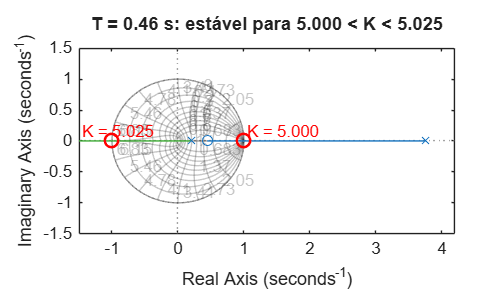

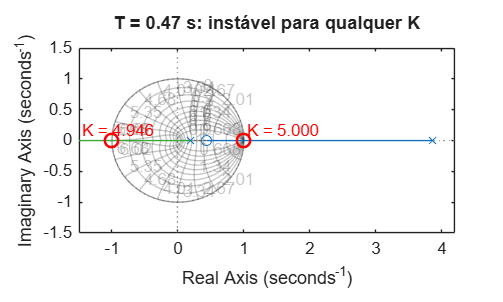

for T_teste = [0.46 0.47]
    sys_discreto_teste = c2d(sys, T_teste, 'zoh');
    K_entra = -1 / evalfr(sys_discreto_teste,  1);   % K no cruzamento em z = 1
    K_sai   = -1 / evalfr(sys_discreto_teste, -1);   % K no cruzamento em z = -1

    figure
    rlocus(sys_discreto_teste)
    zgrid
    axis equal
    xlim([-1.5 4.2]); ylim([-1.5 1.5])
    hold on
    plot([1 -1], [0 0], 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)
    text(1.05, 0.15, sprintf('K = %.3f', K_entra), 'Color', 'r')
    text(-1.45, 0.15, sprintf('K = %.3f', K_sai), 'Color', 'r')
    if K_sai > K_entra
        title(sprintf('T = %.2f s: estável para %.3f < K < %.3f', T_teste, K_entra, K_sai))
    else
        title(sprintf('T = %.2f s: instável para qualquer K', T_teste))
    end
    theme(gcf, 'light')
    exportgraphics(gcf, fullfile(pasta_figuras, sprintf('rlocus_estabilidade_T_%.2f.png', T_teste)), 'Resolution', 300)
    hold off
end

A varredura mostrou que o sistema discreto realimentado só pode ser estabilizado até T ≈ 0,46 s. A frequência mínima de amostragem para estabilidade é, portanto, fs ≈ 2,17 Hz. Em T = 0,46 s, ainda existe uma faixa estável (5 < K < 5,025). Em T = 0,47 s, o root locus não tem mais nenhum trecho dentro do círculo unitário, e nenhum K estabiliza o sistema. Essa frequência garante apenas a estabilidade, sem atender aos requisitos.

Em seguida, verificamos o root locus para vários valores de T, a fim de encontrar a frequência mínima de amostragem que cumpre os requisitos. O círculo vermelho tracejado delimita a região do tempo de estabelecimento, o polo dominante deve ficar dentro dele.

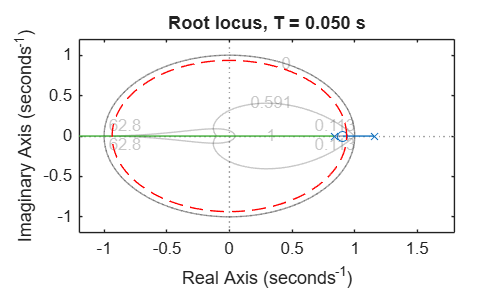

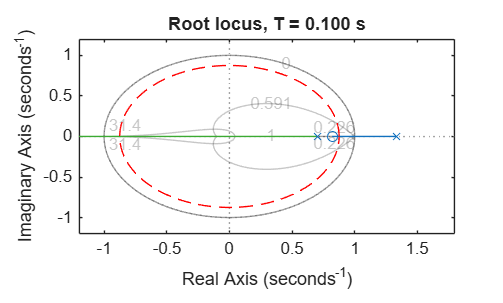

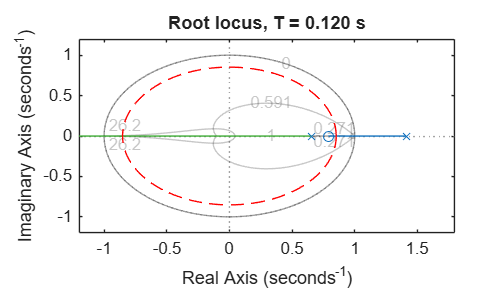

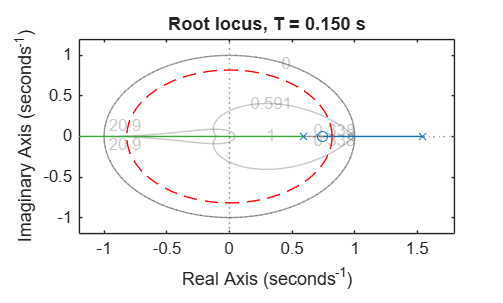

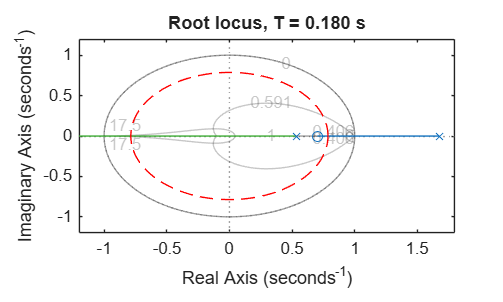

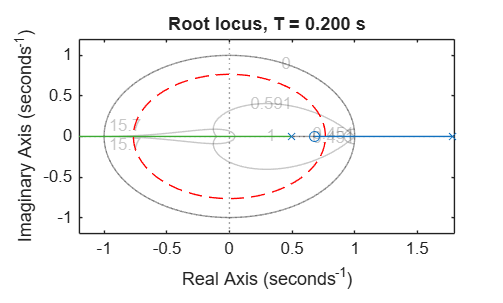

angulos = linspace(0, 2*pi, 200);

for T_teste = [0.05 0.10 0.12 0.15 0.18 0.20]
    sys_discreto_teste = c2d(sys, T_teste, 'zoh');
    figure
    rlocus(sys_discreto_teste)
    zgrid(zeta, wn*T_teste)
    hold on
    raio_ts = exp(-sigma*T_teste);
    plot(raio_ts*cos(angulos), raio_ts*sin(angulos), 'r--')
    axis equal
    xlim([-1.2 1.8]); ylim([-1.2 1.2])
    title(sprintf('Root locus, T = %.3f s', T_teste))
    hold off
    theme(gcf, 'light')
    exportgraphics(gcf, fullfile(pasta_figuras, sprintf('rlocus_requisitos_T_%.3f.png', T_teste)), 'Resolution', 300)
end

Para confirmar, procuramos, para cada T, um ganho K que cumpra os três requisitos. NaN indica que nenhum K cumpre:

for T_teste = [0.05 0.10 0.12 0.15 0.18 0.19 0.20]
    sys_discreto_teste = c2d(sys, T_teste, 'zoh');
    K_ok = NaN;
    for K_teste = 5:0.05:20
        malha = feedback(K_teste*sys_discreto_teste, 1);
        if ~isstable(malha), continue, end
        t = 0:T_teste:20;                                  % horizonte fixo
        y = step(malha, t);
        info = stepinfo(y, t, dcgain(malha));              % valor final exato
        if info.Overshoot <= 10 && info.RiseTime <= 2 && info.SettlingTime <= 3
            K_ok = K_teste;
            break
        end
    end
    fprintf('T = %.3f s | fs = %.2f Hz | K que cumpre: %.2f\n', T_teste, 1/T_teste, K_ok);
end

T = 0.050 s | fs = 20.00 Hz | K que cumpre: 10.05
T = 0.100 s | fs = 10.00 Hz | K que cumpre: 9.75
T = 0.120 s | fs = 8.33 Hz | K que cumpre: 9.65
T = 0.150 s | fs = 6.67 Hz | K que cumpre: 9.55
T = 0.180 s | fs = 5.56 Hz | K que cumpre: 9.45
T = 0.190 s | fs = 5.26 Hz | K que cumpre: NaN
T = 0.200 s | fs = 5.00 Hz | K que cumpre: NaN


Pelo root locus de cada caso, quanto maior o T, menor a região que atende aos requisitos e mais cedo o locus se aproxima de z = −1. Os requisitos foram atendidos até T ≈ 0,18 s e deixaram de ser atendidos em T = 0,20 s. **A frequência mínima de amostragem para cumprir os requisitos é, portanto, fs ≈ 5,6 Hz. **O período adotado, T = 0,12 s (fs ≈ 8,33 Hz), fica dentro dessa faixa com margem, e com K = 12,26 resulta em overshoot nulo e tempo de estabelecimento de aproximadamente 2,28 s.

Por fim, vamos descobrir a taxa de amostragem mínima para o sistema ser emulado, comparando a resposta do sistema controlado analogicamente (mesmo K, sem amostragem) com a do sistema controlado digitalmente e diminuindo T até que coincidam:

sys_analogico = feedback(K*sys, 1);
stepinfo(sys_analogico)

ans = struct with fields:
         RiseTime: 1.1322
    TransientTime: 2.4340
     SettlingTime: 2.4340
      SettlingMin: 1.5205
      SettlingMax: 1.6868
        Overshoot: 0
       Undershoot: 0
             Peak: 1.6868
         PeakTime: 4.7522


y_final = dcgain(sys_analogico);

for T_teste = [0.12 0.10 0.05 0.02 0.015 0.01 0.005]
    sys_digital = feedback(K*c2d(sys, T_teste, 'zoh'), 1);
    t = 0:T_teste:6;
    erro = max(abs(step(sys_digital, t) - step(sys_analogico, t))) / y_final * 100;
    fprintf('T = %.3f s | fs = %.0f Hz | diferença máxima = %.1f %%\n', T_teste, 1/T_teste, erro);
end

T = 0.120 s | fs = 8 Hz | diferença máxima = 47.0 %
T = 0.100 s | fs = 10 Hz | diferença máxima = 34.0 %
T = 0.050 s | fs = 20 Hz | diferença máxima = 10.0 %
T = 0.020 s | fs = 50 Hz | diferença máxima = 3.4 %
T = 0.015 s | fs = 67 Hz | diferença máxima = 2.5 %
T = 0.010 s | fs = 100 Hz | diferença máxima = 1.6 %
T = 0.005 s | fs = 200 Hz | diferença máxima = 0.8 %


A diferença entre as respostas cai com a redução de T. Adotando como critério uma diferença máxima de 2%, as respostas coincidem a partir de T ≈ 0,01 s, e a taxa de amostragem mínima para emulação é fs ≈ 100 Hz. Com o mesmo K em controle analógico, o sistema também cumpre os requisitos (tempo de subida ≈ 1,13 s e tempo de estabelecimento ≈ 2,43 s, sem sobressinal).

Usando T = 0,12 do projeto na primeira figura e T = 0,01 na segunda: